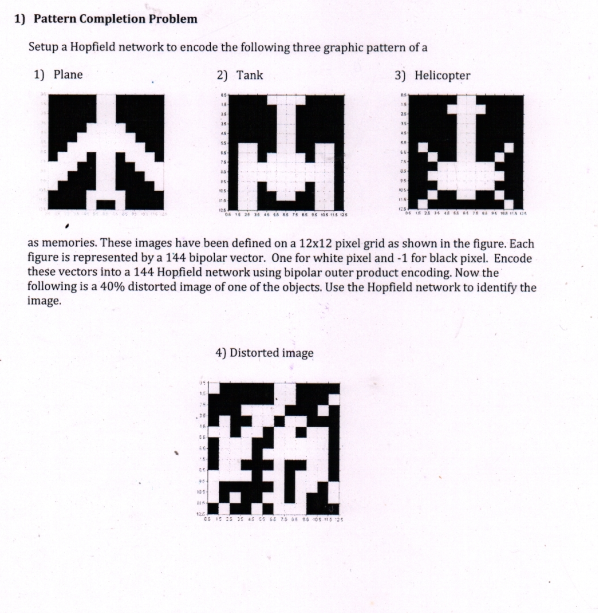

plane = [ -1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	-1;
-1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	-1;
-1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	-1;
-1	-1	-1	-1	1	1	1	1	-1	-1	-1	-1;
-1	-1	-1	1	1	1	1	1	1	-1	-1	-1;
-1	-1	1	1	1	1	1	1	1	1	-1	-1;
-1	1	1	1	-1	1	1	-1	1	1	1	-1;
1	1	1	-1	-1	1	1	-1	-1	1	1	1;
1	1	-1	-1	-1	1	1	-1	-1	-1	1	1;
1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	1;
-1	-1	-1	-1	1	1	1	1	-1	-1	-1	-1;
-1	-1	-1	-1	1	-1	-1	1	-1	-1	-1	-1; ];
tank = [-1	-1	-1	-1	1	1	1	1	-1	-1	-1	-1;
-1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	-1;
-1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	-1;
-1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	-1;
-1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	-1;
-1	1	1	-1	-1	1	1	-1	-1	1	1	-1;
-1	1	1	-1	1	1	1	1	-1	1	1	-1;
-1	1	1	1	1	1	1	1	1	1	1	-1;
-1	1	1	1	1	1	1	1	1	1	1	-1;
-1	1	1	-1	1	1	1	1	-1	1	1	-1;
-1	1	1	-1	-1	1	1	-1	-1	1	1	-1;
-1	1	1	-1	-1	-1	-1	-1	-1	1	1	-1;];
helicopter = [-1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	-1;
-1	-1	-1	-1	1	1	1	1	-1	-1	-1	-1;
-1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	-1;
-1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	-1;
-1	-1	-1	-1	-1	1	1	-1	-1	-1	-1	-1;
-1	1	-1	-1	-1	1	1	-1	-1	-1	1	-1;
-1	-1	1	-1	-1	1	1	-1	-1	1	-1	-1;
-1	-1	-1	1	1	1	1	1	1	-1	-1	-1;
-1	-1	1	1	1	1	1	1	1	1	-1	-1;
-1	-1	-1	1	1	1	1	1	1	-1	-1	-1;
-1	-1	1	-1	-1	1	1	-1	-1	1	-1	-1;
-1	1	-1	-1	-1	-1	-1	-1	-1	-1	1	-1;];

input = containers.Map({1,2,3},{plane,tank,helicopter});

w = zeros(144,144);
for i = 1:3
    a = reshape(input(i),[],1) ;
    w = w + a*a' ;
end

test = [1	-1	-1	-1	-1	-1	1	1	-1	-1	-1	-1;
-1	-1	-1	-1	-1	-1	1	1	-1	-1	-1	1;
-1	-1	-1	1	1	1	1	-1	-1	-1	1	-1;
-1	1	-1	-1	1	1	-1	1	1	-1	-1	-1;
1	1	-1	1	1	-1	1	1	-1	1	1	-1;
-1	1	1	1	-1	-1	1	1	1	1	1	-1;
-1	1	1	1	-1	1	1	1	1	1	1	-1;
-1	1	1	-1	-1	-1	1	-1	-1	1	1	-1;
1	1	1	1	-1	1	1	-1	1	1	1	-1;
1	-1	-1	-1	-1	-1	1	-1	1	1	-1	1;
1	-1	1	-1	-1	1	1	-1	1	-1	-1	1;
-1	1	-1	-1	1	-1	1	1	1	-1	-1	-1;];

a = reshape(test,[],1) ;
out = a'*w ;
for i = 1:size(out,2)
    if out(i) > 0
        out(i) = 1;
    elseif out(i) < 0
        out(i) = -1;
    else
        out(i) = a(i);
    end
end

for i=1:3
    a = reshape(input(i),[],1)' ;
    if a == out
        fprintf("%d is the image",i)
    end
end

1 is the image

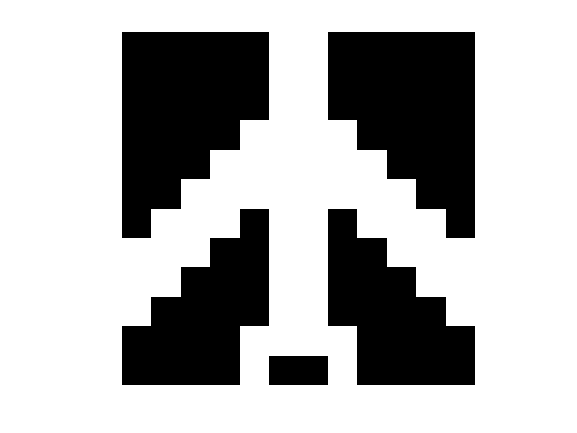

% The test input is distorted image of plane
imshow(reshape(out,12,12))